# Versao 2

clear all;
media=10;
var=5;
length= flow(number(media,var));
letras=['A':'Z','À','Á','Â','Ã','Ç','É','È','Ê','Í','Ì','Î','Ó','Ò','Ô','Õ','Ú','Ù','Û',
        'a':'z','á','à','â','ã','ç','é','è','ê','í','ì','î','ó','ò','ô','õ','ù','ú','û'];
files={'pg21209.txt','pg26017.txt'};
fmp=pmfLetrasPT(files,letras);

Processando pg21209.txt
Processando pg26017.txt
Terminado.


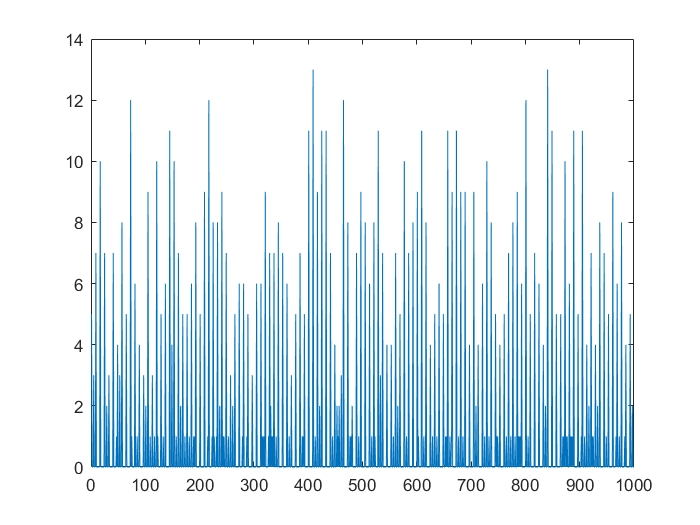

dist=cumsum(fmp);
toPlot=zeros(1,1000);

for i=1:1000
    length=floor(number(media,var));
    chave = keystring(length,dist,letras);
    hash=string2hash(chave,1000)+1;
    toPlot(hash)=toPlot(hash)+1;
end

plot(toPlot)

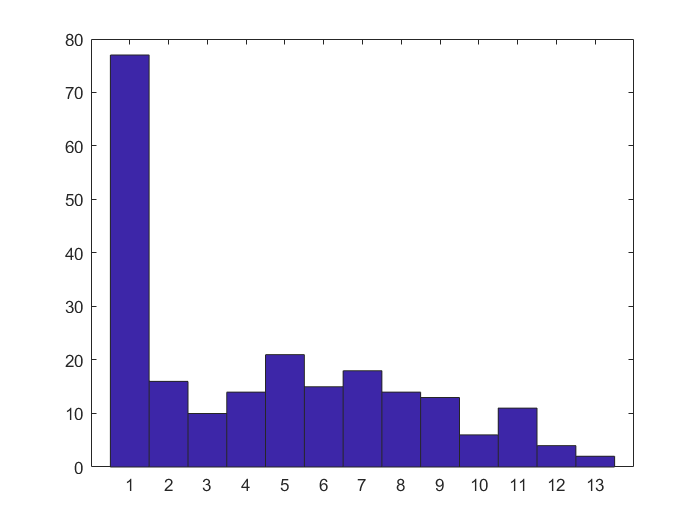

hist(toPlot(toPlot>0), 1:max(toPlot))

function k = keystring(c,dist,pool)
    k='';
    for i=1:c
        indice = find(dist>rand());
        k(i) = pool(indice(1));
    end
end

function n = number(media,var)
    n=rand()*var+media;
end

function hash = string2hash(srt,N) %gerada no ponto 2
    res=0;
    for i=1:length(srt)
        res=srt(i)+res*37; %2^32-1 
    end
    hash=mod(res,N);
end